# MAE 509 Final Project

## b) Random Walk Metropolis/// 

## Last updated by: 

## Haosong Xiao 05:10 pm April 18th

clear all; close all; clc;
%forward = @(x,T,std,);

## Forward Function


forward = @(c1,c2,data_x,gmma,T_amb,parameters) c1*exp(-gmma*data_x)+c2*exp(-gmma*data_x)+T_amb;


## basic parameters


a = 0.95; b = 0.95; L = 70; k = 2.37; T_amb = 21.29; 
phi = -18.41; h = 0.00191; 
n = 15;
data_x = linspace(10, 66, n);
data_T = [96.1 80.12 67.66 57.96 50.90 44.84 39.75 36.16 ...
    33.31 31.15 29.28 27.88 27.18 26.40 25.86];
data_std = [0.2 0.5 0.8 0.45 0.32 0.15 0.7 0.65 ...
    0.54 0.48 0.84 0.56 0.74 0.36 0.75];

## Formulas for forward fucntion

parameters = [h,phi];
% T = c1*exp(-gmma*x)+c2*exp(gmma*x)+T_amb;
gmma = sqrt(2*(a+b)*parameters(1)/(a*b*k));
c1 = -parameters(2)/(k*gmma)*(exp(gmma*L)*(parameters(1)+k*gmma)/(exp(-gmma*L)*(parameters(1)-k*gmma)+exp(gmma*L)*(parameters(1)+k*gmma)));
c2 = parameters(2)/(k*gmma)+c1;
T = c1*exp(-gmma*data_x)+c2*exp(gmma*data_x)+T_amb;

## Computating Synthetic Data from Forward Model

data_T = forward(c1,c2,data_x,gmma,T_amb,[h,phi])

data_T =    95.8065   80.3180   68.0489   58.3299   50.6311   44.5325   39.7014   35.8746   32.8431   30.4418   28.5396   27.0327   25.8391   24.8935   24.1445


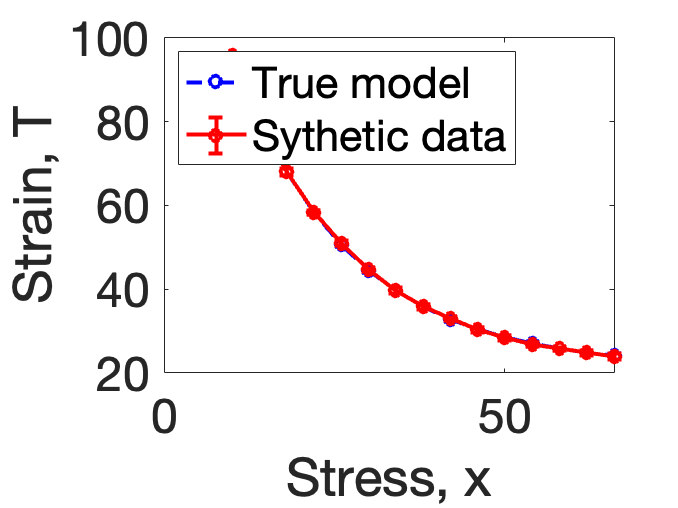

num_exprmt = 15;

T_exprmts=zeros(num_exprmt,length(data_T));
for i = 1:num_exprmt
    T_exprmts(i,:) = data_T + normrnd(0,data_std(i), size(data_T));
end
T_data_mean = mean(T_exprmts);
T_data_stDev = std(T_exprmts);

%plot synthetic data
figure()
plot(data_x, data_T, '--bo', 'LineWidth', 2); hold on;
errorbar(data_x, T_data_mean, T_data_stDev, '-ro', 'LineWidth', 2);
% xlim([25,350])
xlabel('Stress, x')
ylabel('Strain, T')
legend('True model','Sythetic data','location','northwest')
set(gca,'FontSize',24)

## Define Gaussian Prior

% Parameter 1: h
h_min = 0.00192;
h_max = 0.00190;
h_prior_mean = 0.00191;
h_prior_stDev = 0.00191/5;

% Parameter 2: phi
phi_min = -20;
phi_max = -18;
phi_prior_mean = -19;
phi_prior_stDev = 19/10;

% rearrange prior infos
prior_mean = [h_prior_stDev phi_prior_stDev];
prior_var = diag([h_prior_stDev phi_prior_stDev].^2);
lobounds = [h_min,phi_min];
upbounds = [h_max,phi_max];


## Define inputs of Metropolis: initial point and proposal variance

% start at prior means by default
MH_initial = [h_prior_mean  phi_prior_mean];

% MH step size, assumed 1% of prior range here
proposal_variance = [(h_max-h_min)*0.05   (phi_max-phi_min)*0.05 ].^2;  



## Define log_likelihood function

misfit = @(sample) (forward(c1,c2,data_x,gmma,T_amb,sample) - T_data_mean).^2 ./ (T_data_stDev.^2) ;
loglike = @(sample) -sum( 0.5*misfit(sample) );


## Construct a Metropolis chain od length N

N = 1000;
Nparam = length(MH_initial);

% initial sample at MH start
samples(1,:) = MH_initial;

loglike_current = loglike(samples(1,:));
logprior_current = log(  mvnpdf(samples(1,:), prior_mean, prior_var)  );

for i = 2:N
    
    % proposed a parameter sample
    % resample if the sample is not in prior bounds
    in_range = 0; 
    while ~in_range
        proposed_sample = samples(i-1,:) + mvnrnd( [0,0],  diag(proposal_variance)  );
        if sum(  (proposed_sample>upbounds) + (proposed_sample<lobounds)   ) == 0
            in_range = 1;
        end            
    end
    
    loglike_proposal = loglike(proposed_sample);
    logprior_proposal = log(  mvnpdf(proposed_sample, prior_mean, prior_var)  );
    
    
    % acceptance ratio
    accept =  exp(  (loglike_proposal + logprior_proposal) - (loglike_current + logprior_current)  );
    
    if  rand(1) < min(1,accept)
        % accept the proposed sample and update the current infos
        samples(i,:) = proposed_sample;
        loglike_current  = loglike_proposal;
        logprior_current = logprior_proposal;
            
    else
        % reject proposal, stay at the same sample
        samples(i,:) = samples(i-1,:);
        
    end  
end

% burn-in period: 20% of the samples
burn_in = round(N*0.2);


%% Plot MH results


% marginal paths of the chain
figure()
title('Marginal paths')
subplot(1,2,1)
plot(samples(burn_in+1:end,1)); hold on;
plot(0,h, '*', 'Markersize', 15,'LineWidth',3);
xlabel('Chain iteration')
ylabel('E')
set(gca,'FontSize',20)

subplot(1,2,2)
plot(samples(burn_in+1:end,2)); hold on;
plot(0,phi, '*', 'Markersize', 15,'LineWidth',3);
xlabel('Chain iteration')
ylabel('Ty')
set(gca,'FontSize',20)

% marginal posterior distribution
figure()
title('Marginal posterior distributions of parameters')
subplot(1,2,1)
histogram(samples(burn_in+1:end,1),50,'edgecolor','none','Normalization','pdf'); hold on;
plot(h,0,'*', 'Markersize', 15,'LineWidth',3);
Elocs = linspace(lobounds(1),upbounds(1),200);
plot(Elocs,normpdf(Elocs, prior_mean(1), sqrt(prior_var(1,1))  ),'LineWidth',5);
xlim([h_min, h_max])
xlabel('E')
legend('Posterior Samples','True','Prior','location','northwest')
set(gca,'FontSize',20)

subplot(1,2,2)
histogram(samples(burn_in+1:end,2),50,'edgecolor','none','Normalization','pdf'); hold on;
plot(phi,0,'*', 'Markersize', 15,'LineWidth',3);
Tylocs = linspace(lobounds(2),upbounds(2),200);
plot(Tylocs,normpdf(Tylocs, prior_mean(2), sqrt(prior_var(2,2))  ),'LineWidth',5);
xlim([phi_min, phi_max])
xlabel('Ty')
legend('Posterior Samples','True','Prior','location','northwest')
set(gca,'FontSize',20)

% posterior samples
figure
plot(h, phi, 'b*', 'Markersize', 15,'LineWidth',3)
hold on
plot(samples(burn_in+1:end,1), samples(burn_in+1:end,2), 'ro', 'Markersize', 3);
xlabel('E'); xlabel('Ty')
set(gca,'FontSize',24)


% autocorelation
figure
nlags =30;
[ACF_E,lags,bounds] = autocorr(samples(1:end,1), nlags, 0);
[ACF_Ty,lags,bounds]= autocorr(samples(1:end,2), nlags, 0);
plot(lags,ACF_E,'bo-',lags,ACF_Ty,'r*-','linewidth',3);
ylabel('Autocorrelation');
xlabel('Lag');
grid on;
legend('E','Ty');
set(gca,'FontSize',24)


% Covariance and Correlation Matrices
cov_matrix  = cov(samples)
corr_matrix = corr(samples)

